% Rectangular Phased Array Antenna 2D Array Factor Animation

clc, clear, clearvars;

% Define parameters
num_elements_x = 20000;  % Number of elements in x-direction
num_elements_y = 20000;  % Number of elements in y-direction

freq = 10e6;
c =  3e8;
lambda = c/freq;
d = lambda *0.536 % Element spacing (normalized)

d = 16.0800


% Generate a grid of azimuthal and elevation angles
azimuth_angles = linspace(0, 180, 180);
elevation_angles = (linspace(90, 270, 180));

% Define element pattern
EF = 1.5;
[azimuth_grid, elevation_grid] = meshgrid(azimuth_angles, elevation_angles);
EP = cosd(azimuth_grid).^(EF/2);  % Corrected element pattern calculation

% Initialize array factor
array_factor_2d = zeros(size(azimuth_grid));

% Define a sinspace basiss vectors for plotting
sinespaceU = cosd(azimuth_angles).*sind(elevation_angles);
sinespaceV = sind(azimuth_angles).*sind(elevation_angles);

% Compute sinsespace spanned grid
[sinespaceU_grid, sinespaceV_grid] = meshgrid(sinespaceU, sinespaceV);

% Define coordinates for antennas centered
xcoords = -num_elements_x*d/2: d: num_elements_x*d/2

xcoords = 1.0e+05 *

   -1.6080   -1.6078   -1.6077   -1.6075   -1.6074   -1.6072   -1.6070   -1.6069   -1.6067   -1.6066   -1.6064   -1.6062   -1.6061   -1.6059   -1.6057   -1.6056   -1.6054   -1.6053   -1.6051   -1.6049   -1.6048   -1.6046   -1.6045   -1.6043   -1.6041   -1.6040   -1.6038   -1.6037   -1.6035   -1.6033   -1.6032   -1.6030   -1.6029   -1.6027   -1.6025   -1.6024   -1.6022   -1.6021   -1.6019   -1.6017   -1.6016   -1.6014   -1.6012   -1.6011   -1.6009   -1.6008   -1.6006   -1.6004   -1.6003   -1.6001


ycoords = -num_elements_y*d/2: d: num_elements_y*d/2

ycoords = 1.0e+05 *

   -1.6080   -1.6078   -1.6077   -1.6075   -1.6074   -1.6072   -1.6070   -1.6069   -1.6067   -1.6066   -1.6064   -1.6062   -1.6061   -1.6059   -1.6057   -1.6056   -1.6054   -1.6053   -1.6051   -1.6049   -1.6048   -1.6046   -1.6045   -1.6043   -1.6041   -1.6040   -1.6038   -1.6037   -1.6035   -1.6033   -1.6032   -1.6030   -1.6029   -1.6027   -1.6025   -1.6024   -1.6022   -1.6021   -1.6019   -1.6017   -1.6016   -1.6014   -1.6012   -1.6011   -1.6009   -1.6008   -1.6006   -1.6004   -1.6003   -1.6001


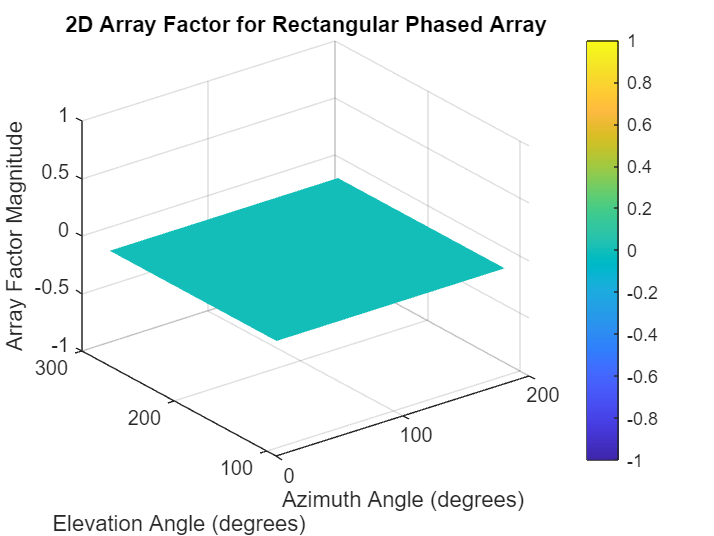



% Set up the figure
figure;
ax = axes;
h = surf(ax,azimuth_grid, elevation_grid, abs(array_factor_2d), 'EdgeColor', 'none');
title('2D Array Factor for Rectangular Phased Array');
xlabel('Azimuth Angle (degrees)');
ylabel('Elevation Angle (degrees)');
zlabel('Array Factor Magnitude');
colorbar;




% Loop through different DOA
parfor i = 1:180
    % Define DOA
    azim_doa = azimuth_angles(i);
    elev_doa = elevation_angles(i);

    % Calculate array factor
    array_factor_2d = zeros(size(azimuth_grid));
    for m = 1:num_elements_x
        for n = 1:num_elements_y
            % Element position in x and y directions
            x_position = xcoords(m);
            y_position = ycoords(n);
            
            % Calculate phase shift for the element
            phase_shift = 2 * (pi/lambda) * (x_position * sind(elevation_grid) .* cosd(azimuth_grid) + y_position * sind(elevation_grid) .* sind(azimuth_grid));
    
            % Calculate phase shift due to DOA
            doa_phase_shift = 2 * (pi/lambda) * (x_position * sind(elev_doa) .* cosd(azim_doa) + y_position * sind(elev_doa) .* sind(azim_doa));
    
            % Accumulate phase shifts for all elements
            array_factor_2d = array_factor_2d + EP .* exp(-1j * phase_shift) .* exp(-1j * doa_phase_shift);
        end
    end
    
    % Normalize array factor
    array_factor_2d = array_factor_2d / (num_elements_y * num_elements_x);

    % Update and draw the plot
    set(h, 'ZData', abs(array_factor_2d));
    drawnow

end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 14 workers.
